# BME3053C Final Project Program

#### Congestive Heart Failure Detection in ECGs using Signal Processing Techniques

Authors: Zaid Abu-Mowis, Cheyenne Ball, Naomi Fils

Course: BME 3053C Computer Applications for BME

Term: Spring 2021

J. Crayton Pruitt Family Department of Biomedical Engineering

University of Florida

Email: zabumowis@ufl.edu, cheyenne.ball@ufl.edu, naomifils@ufl.edu

April 16, 2021

1- ECG Aquisition: Request ECG file from user in .mat format 

clc; clear; clf;

ecg = input('Enter ECG file here: ',"s");               %inputting filename

2 - Load ECG file, correct axis units, label the axes, and display the ECG

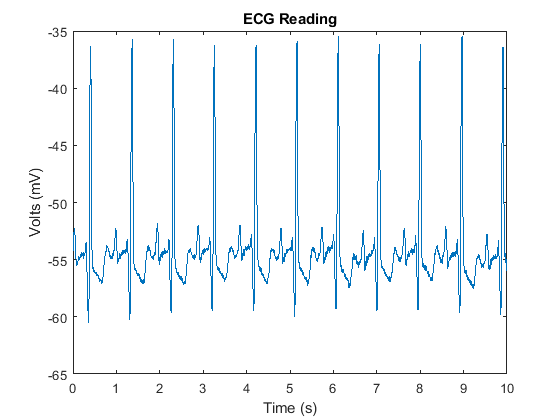

load(ecg);

ecg_volt = val(2,:);                                    % files contain sets of two ECGs from different leads; ECG2 is extracted.
ecg_volt = (ecg_volt-1024)./20;                         % analog values are converted to mV
Fs = 250;                                               % sampling frequency 
t = (0:length(ecg_volt)-1)/Fs;                          % period of ecg reading  

plot(t,ecg_volt)                                        % plotting unedited ECG reading
xlabel('Time (s)')
ylabel('Volts (mV)')
title('ECG Reading')

3 - ECG Preprocessing: Filter and normalize the ECG against the x-axis

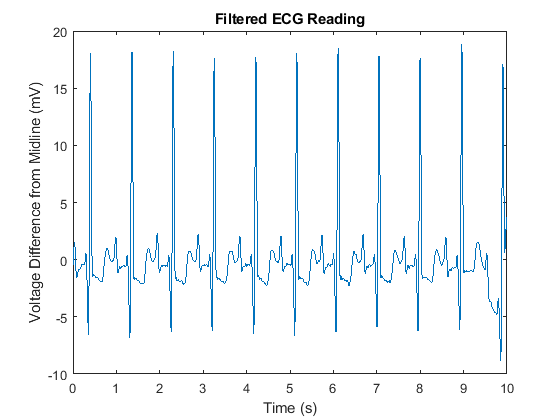

L = length(ecg_volt);                                   % Signal Length (samples)
Fn = Fs/2;                                              % Nyquist Frequency
Wp = [1  100]/Fn;                                       % Passband (Normalised)
Ws = [0.5  110]/Fn;                                     % Stopband (Normalised)
[n,Ws] = cheb2ord(Wp, Ws, 10, 30);                      % Chebyshev Type II Order
[b,a] = cheby2(n, 30, Ws);                              % Transfer Function Coefficients
[sos,g] = tf2sos(b,a);                                  % Second-Order-Section For Stability
ecg_detrend = filtfilt(sos, g, ecg_volt);

ecg_filt = sgolayfilt(ecg_detrend,5,21);                % Denoising the signal using Savitzky-Golay filter

plot(t,ecg_filt)                                        % Plotting filtered ECG reading
title('Filtered ECG Reading')
xlabel('Time (s)')
ylabel('Voltage Difference from Midline (mV)')

4- Heart Rate Detection: 

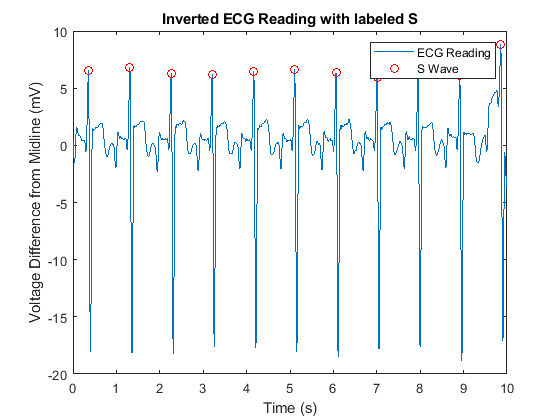

ecg_invert = -ecg_filt;                                 % Invert/Flip the signal
highesttrough = mean(maxk(findpeaks(ecg_invert),3));    % Finding the average value of the 3 highest throughs to account for outliers
[ecg_qrs, t1] = findpeaks(ecg_invert,'MinPeakHeight', highesttrough/1.5); % Finding the troughs of the graph
t1 = t1/Fs;                                             % Accounting for sampling rate

plot(t,ecg_invert)                                      % Plotting the inverted ECG graph with the peaks labeled with red circles
hold on
plot(t1,ecg_qrs,'ro')
hold off
title('Inverted ECG Reading with labeled S')
xlabel('Time (s)')
ylabel('Voltage Difference from Midline (mV)')
legend('ECG Reading','S Wave')



bpm = length(ecg_qrs)*6;                                % Calculating Heart Rate

5- Congestive Heart Failure Detection

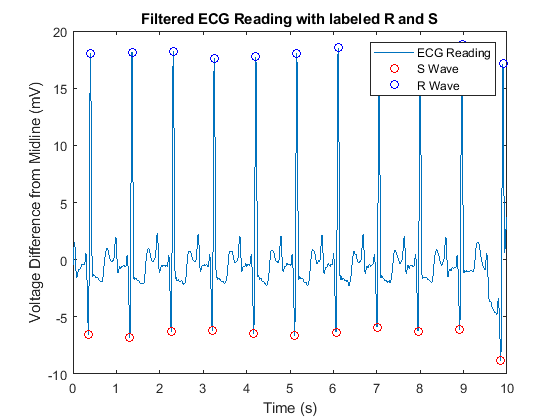

highestpeaks = mean(maxk(findpeaks(ecg_filt),3));       %Finding all of the peaks
[ecg_qrs1, t2] = findpeaks(ecg_filt,'MinPeakHeight', highestpeaks/1.5, 'MinPeakDistance',0.5*Fs); % Sorting the peaks and finding the QR complex peaks
t2 = t2/Fs;                                             % Accounting for sampling rate

ecg_qrs = -ecg_qrs;                                     % Inverting the graph

plot(t,ecg_filt)
hold on
plot(t1,ecg_qrs,'ro')
hold on
plot(t2,ecg_qrs1,'bo')                                  % Plotting the filtered graph with peaks (blue circles) and throughs (red circles)
title('Filtered ECG Reading with labeled R and S')
xlabel('Time (s)')
ylabel('Voltage Difference from Midline (mV)')
legend('ECG Reading','S Wave','R Wave')


chf = false;                                            % Set condition to false until proven true
for i = 1:length(ecg_qrs1)
    if t2(i)-t1(i)>-0.4 && t2(i)-t1(i)<0                % Finding the difference between peaks and troughs to determine CHF
        continue;
    elseif t2(i)-t1(i)<0.4 && t2(i)-t1(i)>0             
        fprintf('Patient has Congestive Heart Failure!')
        chf = true;
        break
    end
end

Patient has Congestive Heart Failure!


if chf == false
    fprintf('Patient has a normal ECG Reading!')
end

fprintf('Patient heart rate is %d beats per minute',bpm)

Patient heart rate is 66 beats per minute